close all;
clear all;

## Définition du mouvement

% Vitesse du mobile
vmax = 1;  % m/s

% accélération du mobile
amax = 5; % m/s²

% Position initiale
x_i = 0; % mm
y_i = 0; % mm
theta_i = 0; % rad

% Position finale
x_f = 500; % mm
y_f = 600; % mm
theta_f = 0; % rad

distance = sqrt(x_f^2+y_f^2);
 

## Définition des constantes

% Hauteur mobile
% Largeur mobile
% Rayon du tambour
R_t = 25; % mm
% Temps d'échantillonnage
dt = 0.001 ;

## Définition des lois en trapèze de vitesse

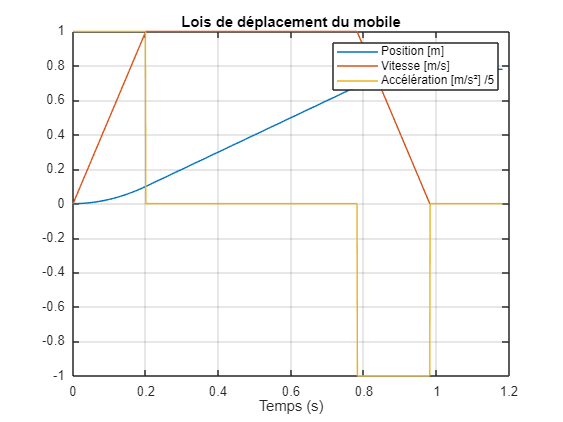

cla()
[les_t,les_x,les_v,les_a] = calcule_profil(amax,vmax,distance,dt);
plot(les_t,les_x,les_t,les_v,les_t,les_a/5 )
xlabel('Temps (s)');
grid on;
legend('Position [m]', ...
     'Vitesse [m/s]', ...
     'Accélération [m/s²] /5')
title("Lois de déplacement du mobile")

### Tracé de la trajectoire du mobile sur l'espace de travail

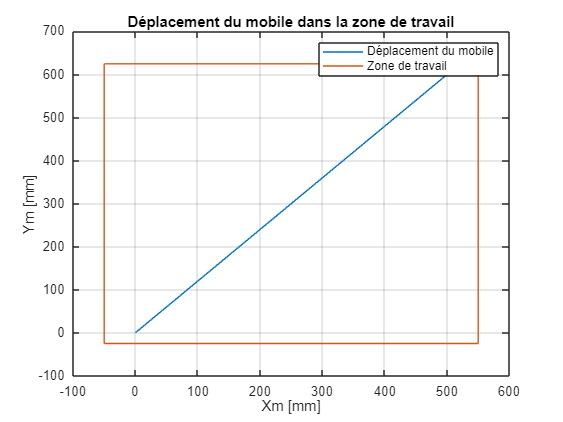

cla()
[les_t,les_xm,les_ym] = trajectoire_mobile(x_i,y_i,x_f,y_f,amax,vmax,dt);
% ZONE DE TRAVAIL A VERIFIER
xt = [-50,550,550,-50,-50];
yt = [-25,-25,625,625,-25];

plot(les_xm,les_ym,xt,yt)%,label = "Position mobile");
grid on;
xlabel('Xm [mm]');
ylabel('Ym [mm]');
legend("Déplacement du mobile","Zone de travail")
title("Déplacement du mobile dans la zone de travail")

### Déplacement du mobile

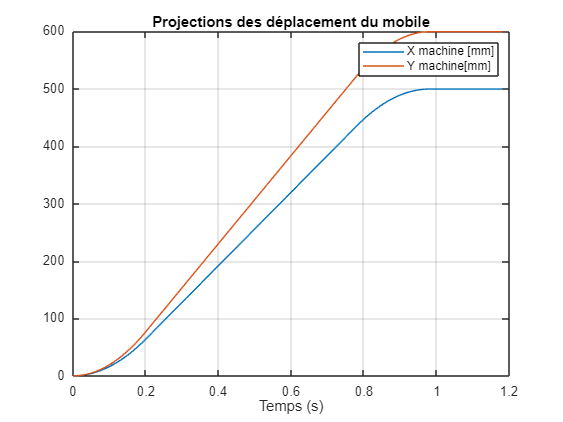

cla()
plot(les_t,les_xm, les_t,les_ym )
grid on
xlabel('Temps (s)');
legend("X machine [mm]","Y machine[mm]")
title("Projections des déplacement du mobile")

### Tracé de la longueur des câbles

#### Calcul des longueurs

% les_BG = [get_L_phi(les_xm[i],les_ym[i],0,"BG")[1] for i in range(len(les_xm))]
% les_BD = [get_L_phi(les_xm[i],les_ym[i],0,"BD")[1] for i in range(len(les_xm))]
% les_HG = [get_L_phi(les_xm[i],les_ym[i],0,"HG")[1] for i in range(len(les_xm))]
% les_HD = [get_L_phi(les_xm[i],les_ym[i],0,"HD")[1] for i in range(len(les_xm))]

les_bg = [];
les_bd = [];
les_hg = [];
les_hd = [];
for i =1:length(les_xm)
    [bg,phi] = get_L_phi(les_xm(i),les_ym(i),0,"BG");
    [bd,phi] = get_L_phi(les_xm(i),les_ym(i),0,"BD");
    [hg,phi] = get_L_phi(les_xm(i),les_ym(i),0,"HG");
    [hd,phi] = get_L_phi(les_xm(i),les_ym(i),0,"HD");
    les_bg(end+1) = bg;
    les_bd(end+1) = bd;
    les_hg(end+1) = hg;
    les_hd(end+1) = hd;
end

#### Tracé en mm

% tiledlayout(2,2)
% nexttile
% plot(les_t,les_hg)
% grid on
% title("HG")
% 
% nexttile
% plot(les_t,les_hd)
% grid on
% title("HD")
% 
% nexttile
% plot(les_t,les_bg)
% grid on
% title("BG")
% 
% nexttile
% plot(les_t,les_bd)
% grid on
% title("BD")

#### Conversion en points

les_hg_qc = 8192*les_hg/R_t/2/pi;
les_hd_qc = 8192*les_hd/R_t/2/pi;
les_bg_qc = 8192*les_bg/R_t/2/pi;
les_bd_qc = 8192*les_bd/R_t/2/pi;

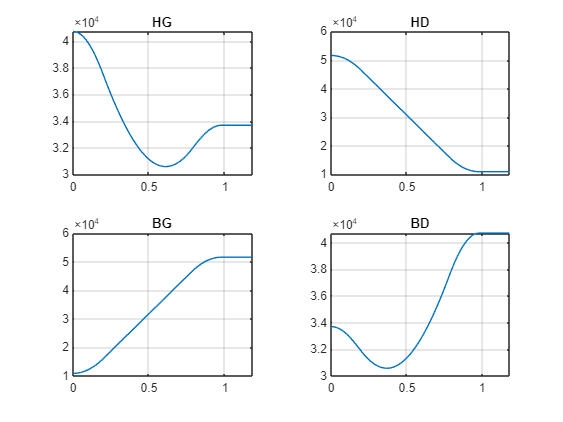

cla()
tiledlayout(2,2)
nexttile
plot(les_t,les_hg_qc)
grid on
title("HG")

nexttile
plot(les_t,les_hd_qc)
grid on
title("HD")

nexttile
plot(les_t,les_bg_qc)
grid on
title("BG")

nexttile
plot(les_t,les_bd_qc)
grid on
title("BD")

## Import de données expérimentales

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [16, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["Index", "Temps", "Var3", "ConsigneDePosition", "PositionAxe", "ConsigneDeVitesse"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Temps", "TrimNonNumeric", true);
opts = setvaropts(opts, "Temps", "ThousandsSeparator", ",");

% Import the data
les_hd_qc_mes = readtable("C:\GitHub\TP_Documents_PSI\16_RC4\Modeles\Modele_causal_Simulink\01\01_HD.csv", opts);

% Clear temporary variables
clear opts

% Set up the Import Options and import the data
opts2 = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts2.DataLines = [16, Inf];
opts2.Delimiter = ";";

% Specify column names and types
opts2.VariableNames = ["Index", "Temps", "Var3", "ConsigneDePosition", "PositionAxe", "ConsigneDeVitesse"];
opts2.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Specify variable properties
opts2 = setvaropts(opts2, "Temps", "TrimNonNumeric", true);
opts2 = setvaropts(opts2, "Temps", "ThousandsSeparator", ",");

% Import the data
les_hg_qc_mes = readtable("C:\GitHub\TP_Documents_PSI\16_RC4\Modeles\Modele_causal_Simulink\01\01_HG.csv", opts2);

% Clear temporary variables
clear opts2

% Set up the Import Options and import the data
opts3 = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts3.DataLines = [16, Inf];
opts3.Delimiter = ";";

% Specify column names and types
opts3.VariableNames = ["Index", "Temps", "Var3", "ConsigneDePosition", "PositionAxe", "ConsigneDeVitesse"];
opts3.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts3.ExtraColumnsRule = "ignore";
opts3.EmptyLineRule = "read";

% Specify variable properties
opts3 = setvaropts(opts3, "Temps", "TrimNonNumeric", true);
opts3 = setvaropts(opts3, "Temps", "ThousandsSeparator", ",");

% Import the data
les_bd_qc_mes = readtable("C:\GitHub\TP_Documents_PSI\16_RC4\Modeles\Modele_causal_Simulink\01\01_BD.csv", opts3);

% Clear temporary variables
clear opts3

% Set up the Import Options and import the data
opts4 = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts4.DataLines = [16, Inf];
opts4.Delimiter = ";";

% Specify column names and types
opts4.VariableNames = ["Index", "Temps", "Var3", "ConsigneDePosition", "PositionAxe", "ConsigneDeVitesse"];
opts4.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts4.ExtraColumnsRule = "ignore";
opts4.EmptyLineRule = "read";

% Specify variable properties
opts4 = setvaropts(opts4, "Temps", "TrimNonNumeric", true);
opts4 = setvaropts(opts4, "Temps", "ThousandsSeparator", ",");

% Import the data
les_bg_qc_mes = readtable("C:\GitHub\TP_Documents_PSI\16_RC4\Modeles\Modele_causal_Simulink\01\01_BG.csv", opts4);

% Clear temporary variables
clear opts4

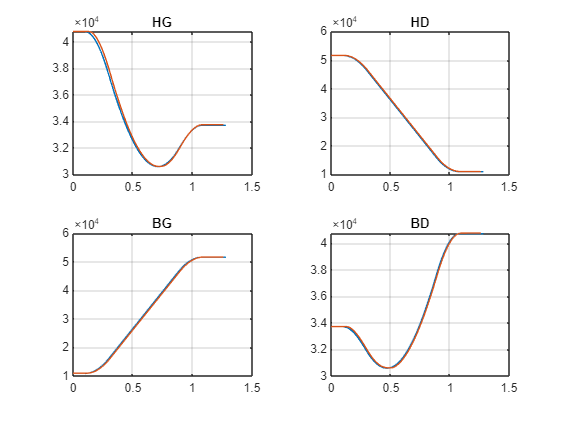

cla()
dec_t = 0.1;
tiledlayout(2,2)
nexttile
%plot(les_t,les_hg_qc,les_hg_qc_mes.Temps/1000,les_hg_qc,les_hg_qc_mes.PositionAxe)
plot(les_t+dec_t,les_hg_qc,les_hg_qc_mes.Temps(2:end-10)/10000,les_hg_qc_mes.PositionAxe(2:end-10))
grid on
title("HG")

nexttile
plot(les_t+dec_t,les_hd_qc,les_hd_qc_mes.Temps(2:end-10)/10000,les_hd_qc_mes.PositionAxe(2:end-10))
grid on
title("HD")

nexttile
plot(les_t+dec_t,les_bg_qc,les_bg_qc_mes.Temps(2:end-10)/10000,les_bg_qc_mes.PositionAxe(2:end-10))
grid on
title("BG")

nexttile
plot(les_t+dec_t,les_bd_qc,les_bd_qc_mes.Temps(2:end-10)/10000,les_bd_qc_mes.PositionAxe(2:end-10))
grid on
title("BD")

% figure
% 
les_hd_ts = timeseries(les_hd,les_t,"Name","HD_mm");
les_hg_ts = timeseries(les_hg,les_t,"Name","HD_mm");
les_bd_ts = timeseries(les_bd,les_t,"Name","HD_mm");
les_bg_ts = timeseries(les_bg,les_t,"Name","HD_mm");

% les_hd_ts.Data = les_hd_ts.Data - les_hd_ts.Data(1);
% les_hg_ts.Data = les_hg_ts.Data - les_hg_ts.Data(1);
% les_bd_ts.Data = les_bd_ts.Data - les_bd_ts.Data(1);
% les_bg_ts.Data = les_bg_ts.Data - les_bg_ts.Data(1);
% plot(ts)
% max(les_hd)

les_hg_mes = les_hg_qc_mes.PositionAxe(2:end-10)/8192 * R_t * 2 *pi

les_hg_mes =   781.5824
  781.5824
  781.5824
  781.5824
  781.5824
  781.5824
  781.5824
  781.5824
  781.5824
  781.5632


les_hd_mes = les_hd_qc_mes.PositionAxe(2:end-10)/8192 * R_t * 2 *pi;
les_bg_mes = les_bg_qc_mes.PositionAxe(2:end-10)/8192 * R_t * 2 *pi;
les_bd_mes = les_bd_qc_mes.PositionAxe(2:end-10)/8192 * R_t * 2 *pi;

L_HD = les_hd(1);
L_HG = les_hg(1);
L_BD = les_bd(1);
var = [L_HD,L_HG,L_BD];

fun = @(x)modele_direct(x,var);
% 
x0 = [0,0,0,0,0,0];
x = fsolve(fun,x0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =    -8.7495  -14.1839    0.1799    0.8941    1.6833   -0.2651


%% RESOLUTION DIRECTE SUR LE MODELE 
les_XM = [];
les_YM = [];
les_THETA = [];
les_PHIhd = [];
les_PHIhg = [];
les_PHIbd = [];
x0 = [0,0,0,0,0,0];
options = optimset('Display','off');
fun = @(x)modele_direct(x0,var);
x = fsolve(fun,x0,options);

for i =1:length(les_hd)
    L_HD = les_hd(i);
    L_HG = les_hg(i);
    L_BD = les_bd(i);
    var = [L_HD,L_HG,L_BD];
    fun = @(x)modele_direct(x,var);
    x = fsolve(fun,x0,options);
    
    les_XM(end+1) = x(1);
    les_YM(end+1) = x(2);
    les_THETA(end+1) = rad2deg(x(3));
    les_PHIhd(end+1) = rad2deg(x(4));
    les_PHIhg(end+1) = rad2deg(x(5));
    les_PHIbd(end+1) = rad2deg(x(6));
end

%% RESOLUTION DIRECTE SUR LA MESURE 
les_XM_mes = [];
les_YM_mes = [];
les_THETA_mes = [];
les_PHIhd_mes = [];
les_PHIhg_mes = [];
les_PHIbd_mes = [];
x0 = [0,0,0,0,0,0];
options = optimset('Display','off');
fun = @(x)modele_direct(x,var);
x = fsolve(fun,x0,options);

for i =1:length(les_hd_mes)
    L_HD_mes = les_hd_mes(i);
    L_HG_mes = les_hg_mes(i);
    L_BD_mes = les_bd_mes(i);
    var = [L_HD_mes,L_HG_mes,L_BD_mes];
    fun = @(x)modele_direct(x,var);
    x = fsolve(fun,x0,options);
    
    les_XM_mes(end+1) = x(1);
    les_YM_mes(end+1) = x(2);
    les_THETA_mes(end+1) = rad2deg(x(3));
    les_PHIhd_mes(end+1) = rad2deg(x(4));
    les_PHIhg_mes(end+1) = rad2deg(x(5));
    les_PHIbd_mes(end+1) = rad2deg(x(6));
end

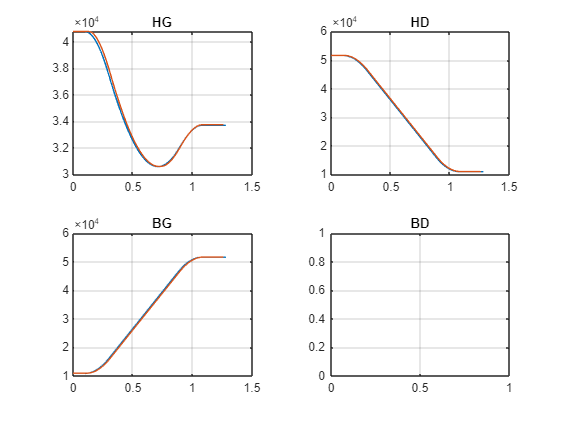

cla()

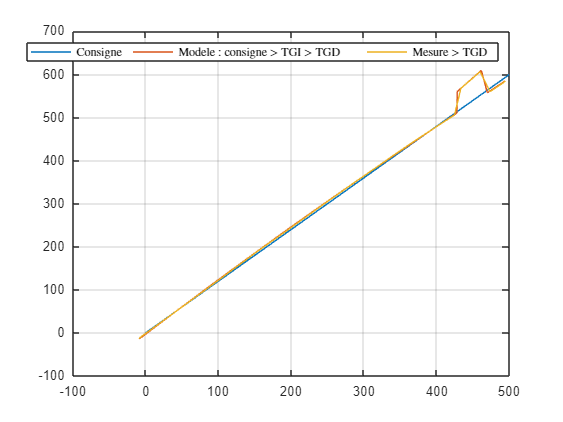

figure()
plot(les_xm,les_ym,les_XM,les_YM,les_XM_mes,les_YM_mes)
grid on
legend('Consigne ', ...
     'Modele : consigne > TGI > TGD', ...
     'Mesure > TGD ','Interpreter','latex')
legend('Orientation','horizontal')

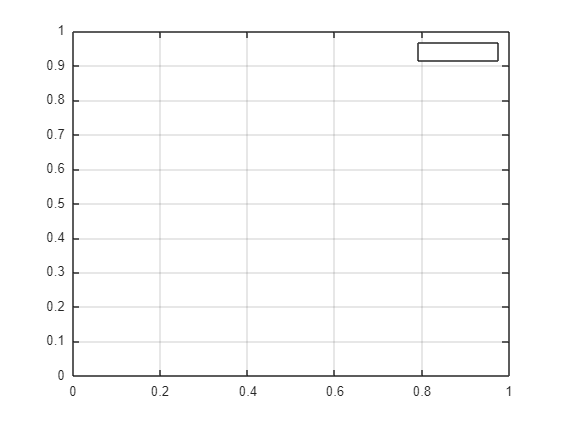

cla()

figure()
plot(les_t,les_PHIhd,les_t,les_PHIhg,les_t,les_PHIbd)
grid on
legend('$\varphi_{HD}$ [deg]', ...
     '$\varphi_{HG}$ [deg]', ...
     '$\varphi_{BD}$ [deg]','Interpreter','latex')